# Ayudantía ADG 

#### CORRELACIONES 2D 

10/07/2023 

Por Scarlett Moraga 

#### Revisaremos los conceptos básicos de la correlación entre dos variables, cómo se construye, su relación con distintos estadísticos, tipos, etc. 

### ¿Qué es la correlación? 

Representa cómo se mueven en conjunto 2 variables y si existe una relación lineal entre ellas; evaluamos la tendencia de los datos 

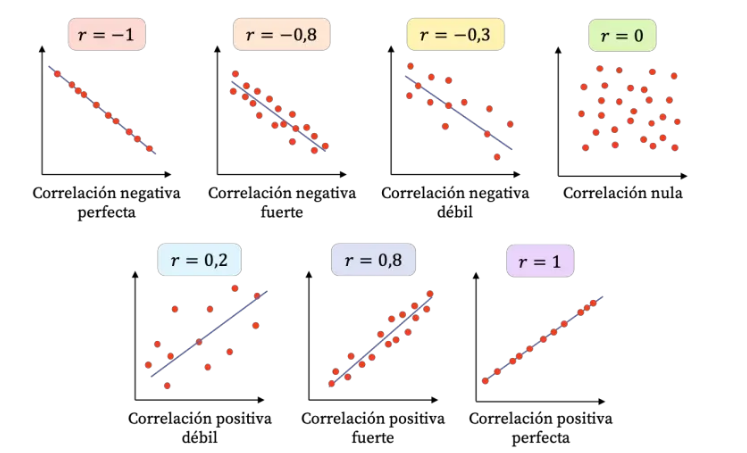

Signo: indica la dirección de la relación 

Magnitud: indica la fuerza de la relación; mientras mayor es el coeficiente más fuerte es la tendencia (menor dispersión de los datos)

#### Importante: La correlación no implica causalidad

## Ejercicio 1: Análisis simple 

#### Cree un vector x=1:50 e un vector y=2x+10  y a su vez un vector y2=x^2. Grafique en un subplot 'x' con respecto a 'y' y 'x' con respecto a 'y2' en un diagrama de puntos (scatter por ejemplo). ¿Qué diferencia a las dos nubes de puntos? ¿Qué tipo de relación existe? ¿Qué correlación creen que exista entre las variables? 

clear all; close all; clc; 

% visualizacion datos
x=1:50;
y=2*x+10;

y2=x.^2;

figure(1)
subplot 121
scatter(x,y,'k','LineWidth',2)
title('Funcion lineal','FontSize',12)
legend('y=2x+10','Location','best')
grid minor 
axis tight 
subplot 122
scatter(x,y2,'r','LineWidth',2)
title('Funcion cuadrática','FontSize',12)
legend('y=x^2','Location','best')
grid minor 
axis tight

## Tipos de correlación

## Ejercicio 2: Spearman y Pearson. 

#### Busque información sobre correlación de Spearman y de Pearson. En el caso del ejercicio 1, ¿qué tipo de correlación deberíamos aplicar para cada caso? Busque información sobre la función 'corr' en Matlab. 

####  Calcule la correlación entre 'x' e 'y', y además la correlación entre 'x' e 'y2'. ¿Qué correlación es mayor?

#### ¿Qué ocurriría con las correlaciones calculadas anteriormente si a los datos se les agrega un valor escapado (outlier)? Compruébelo. 

Pear1=corr(x',y','Type','Pearson'); % corr funciona con matrices columnares 
disp("Coeficiente de correlación:");
disp(Pear1);

Pear=corr(x',y2','Type','Pearson');
disp("Coeficiente de correlación:");
disp(Pear);

Sp1=corr(x',y','Type','Spearman');
disp("Coeficiente de correlación:");
disp(Sp1);

Sp=corr(x',y2','Type','Spearman');
disp("Coeficiente de correlación:");
disp(Sp);

%valores NaN 

x(51)=-999;
y3=2*x+10;
y4=x.^2;

Pear3=corr(x',y3','Type','Pearson'); %ecuacion de la recta con outlier; pearson
disp("Coeficiente de correlación:");
disp(Pear3);

Pear4=corr(x',y4','Type','Pearson'); % ecuacion cuadratica con outlier: pearson
disp("Coeficiente de correlación:");
disp(Pear4);

Sp3=corr(x',y3','Type','Spearman'); % ecuacion de la recta con outlier; spearman
disp("Coeficiente de correlación:");
disp(Sp3);

Sp4=corr(x',y4','Type','Spearman'); % ecuacion cuadratica con outlier; spearman 
disp("Coeficiente de correlación:");
disp(Sp4);


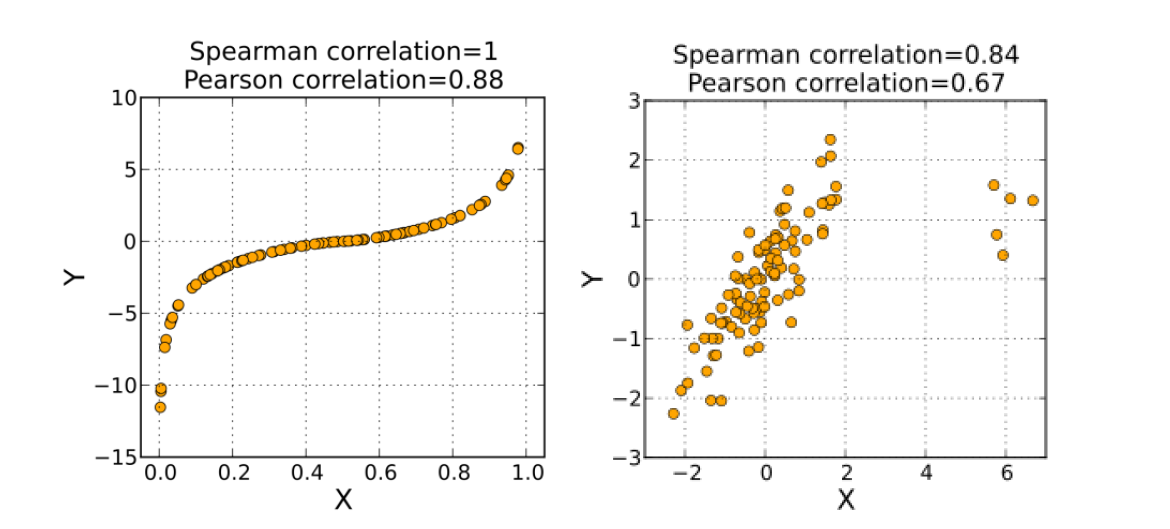 

#### Spearman es menos sensible que la correlación de Pearson frente a los valores atípicos. 

## Ejercicio 3: Manejo de datos 

### a) Grafique las 3 bases de datos entregadas con respecto al tiempo en una misma figura pero en distintos gráficos (subplot). Procure que el gráfico se presente de buena manera. 

clear all; close all; clc; 

% datos mensuales; 2003 a 2013
n34=importdata('N34.mat'); % niño 34 
calor=importdata('CALOR.mat'); % calor contenido en los primeros 700m desde la sup del mar
swl=importdata('swl.mat'); % nivel del mar promedio global

% plot 
subplot 311
plot(n34(:,1),n34(:,2),'k','LineWidth',2)
xlabel('Tiempo','FontSize',12)
ylabel('N34','FontSize',12)
axis tight
grid minor
subplot 312
plot(calor(:,1),calor(:,2),'k','LineWidth',2)
xlabel('Tiempo','FontSize',12)
ylabel('Calor','FontSize',12)
axis tight
grid minor
subplot 313
plot(swl(:,1),swl(:,2),'k','LineWidth',2)
xlabel('Tiempo','FontSize',12)
ylabel('Nivel del mar promedio','FontSize',12)
axis tight
grid minor


#### b) Genere diagramas de dispersión (scatter) entre N34 y el calor, N34 y el nivel del mar promedio y calor junto a nivel del mar promedio. Comente lo observado

figure()
subplot 311
scatter(n34(:,2),calor(:,2),'b',"filled")
xlabel('N34','FontSize',12)
ylabel('Calor','FontSize',12)
grid minor 
axis tight
subplot 312
scatter(n34(:,2),swl(:,2),'r',"filled")
xlabel('N34','FontSize',12)
ylabel('Nivel del mar promedio','FontSize',12)
grid minor 
axis tight
subplot 313 
scatter(calor(:,2),swl(:,2),'k','filled')
xlabel('Calor','FontSize',12)
ylabel('Nivel del mar promedio','FontSize',12)
grid minor 
axis tight



#### c) Calcule las correlaciones entre las series graficadas en b)

a= corr(n34(:,2),calor(:,2)); 
b= corr(n34(:,2),swl(:,2));
c= corr(calor(:,2),swl(:,2));


#### d) ¿Qué sucede con las correlaciones al extraer la tendencia de los datos? 

a1= corr(detrend(n34(:,2)),detrend(calor(:,2))); 
b1= corr(detrend(n34(:,2)),detrend(swl(:,2)));
c1= corr(detrend(calor(:,2)),detrend(swl(:,2)));